# How Do Differences in Certainty Compound for Various Evidence Integration Strategies?

Martynas Snarskis

## Setting Up the Problem

Decision-making has been very successfully modeled by Bayesian Inference models. We are interested in how differences in certainty over stimulus variables $X_i$ affect the certainty of the decision variable $R$ for various evidence integration strategies. Let $k$ represent the number of frames over which to combine stimulus, so that each trial of the task is represented by stimulus $X_{1...k}=\langle X_1,...,X_k \rangle$ where each $X_i \in \{0,1\}$is a binary random variable that represents the presence or absence of signal in that particular frame. For simplicity, we assume correctly detecting each frame is equiprobable, so that $P(X_i | R) = \alpha$ for all $i\in \{1,...,k\}$. We also assume all priors are uninformative.

Using causal infernence (cross-modal cue combination), we can effectively increase the value of $\alpha$ for subjects -- a signature of performing approximate inference. For our purposes (creating a task in which we can use causal inference to reasonably maximize a subjects performance to measure), we're interested in how $P(R=r|X_{1...k})$ changes for a range of improvements of $\alpha$ for some $k$. 

The generality if this setup allows us to use combinatorics to describe all the different ways a subject can perceive/misperceive the stimulus in a trial. Letting $\alpha$ represent perceiving a frame and $(1-\alpha)$ represent misperceiving a frame, we have


$$[\alpha + (1-\alpha)]^k = \alpha^k + {k\choose{1}}\alpha^{k-1}(1-\alpha) + \cdots + {k\choose{k-1}}\alpha(1-\alpha)^{k-1} + (1-\alpha)^k = 1$$


We can describe a number of task strucutures (corresponding to different integration strategies) using this setup.

## Binary Word-Matching Task

In this task, the goal is to select the $r\in R \subset \{0,1\}^k$ such that $r=X_{1...k}$. Note that the number of possible choices $|R|$ grows exponentionally with the number of frames $k$, so that $|R|=2^k$. 

This task requires that the presence or absence of a stimulus is correctly detected in each frame. If the probability of detecting any single frame correct is $P(X_i|R)=\alpha$, then the probability of answering correctly is


$$P(R=r|X_{1...k})=\prod_{i=1}^k P(X_i|R) = \alpha^k$$


We can also determine the probability of choosing a particular incorrect answer. Let $\bar S_m$ refer to the class of choices that have $m$ frames mismatched between the correct choice $r_0=X_{1...k}$. For example, if all $X_i=0$, then $\bar S_1$ contains all choices $r_1$ such that each has exactly one $1$ in the vector (e.g. $\langle 1,0,0,... \rangle$or $\langle 0,1,0,0,... \rangle$). For any $r_m \in \bar S_m$, the probability of responding $r_m$ is 


$$P(R=r_m | X_{1...k}) = \alpha^{k-m} (1-\alpha)^m$$


Note that because $\alpha \geq 0.5$, we have $P(R=r_0|X_{1...k}) \geq ... \geq P(R=r_k|X_{1...k})$. That is, not all answers are equally wrong -- choosing an answer $r_k \in \bar S_k$ requires misperceiving every single frame, which is much less likely than misperceiving a single frame.

Were interested in seeing how the probability of answering correctly changes as we improve $\alpha$. 

alpha = linspace(0.5,1,100);  % frame detection rate
imp = linspace(0,.2,4);     % amount of improvement (0% - 20%)

K = 1:10; % num frames

bin_word = repmat(alpha, size(imp,2), 1, size(K,2)); % init P(R=r|X) matrix

% simulate
for i=1:size(imp,2)
    for k=K
        bin_word(i,:,k) = min( ones(size(bin_word(i,:,k))),...
            bin_word(i,:,k).*(1+imp(i)) ).^k;
    end
end

total_improvement1 = bin_word - bin_word(1,:,:);

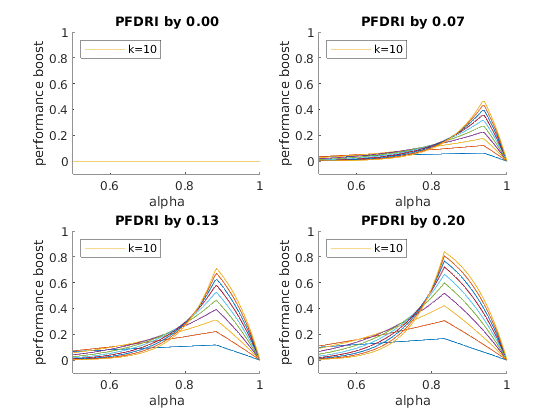

% plot
figure

for i=1:size(imp,2)
    subplot(2, ceil(size(imp,2)/2), i);
    hold on
    
    for k=K
        p = plot(alpha, total_improvement1(i,:,k));
        legend(p, sprintf('k=%d', k), 'Location', 'northwest');
    end
    
    title(sprintf("PFDRI by %0.2f", imp(i)));
    xlabel("alpha");
    ylabel("performance boost");
    
    xlim([0.5 1]);
    ylim([-0.1, 1]);
end

hold off

Above we see how much of a boost in perforance (increase in probability of getting the correct answer) we can get from different per frame detection rate improvements (PFDRI). We see that as we increase the per frame detection rate the perfomance (on average) increases, as expected. As we increase $k$, we see the maximum improvement (with respect to baseline detection rates $\alpha$) increase as well. You may also notice that for small $\alpha$ (e.g. chance performance) the amount of improvement actually decreases with $k$...however, this is likely due to the fact performance overall decreases with $k$ for this task structure.

## Signal Detection Task

In this task, the goal is to determine whether a particular signal has been seen in any frame. This is a two-choice task, with $R=1$ corresponding to the presence of signal and $R=0$ representing the complete absence of the signal. We represent the presence of the relevent signal with $X_i=1$. Again, the probability of detecting the signal (or its absence) is assumed to be equiprobable per frame $P(X_i|R)=\alpha$. An example task would be to determine if any visual stimuli presented across frames is red (shapes can be red or blue). Note that for this task, the stimuli in each frame $X_i$ are not independant, even when conditioning on $R$ (unless $R=0$, in which case each frame MUST be $X_i=0$). 

We can partition the stimuli into classes $\bar X_{1...k}^s$ corresponding to the number of frames $s\in \{1,..,k\}$ that contain the relevant signal, so that $X_{1...k}^0$ corresponds to $R=0$, while all other values of $s$ correspond to $R=1$. Then the probability of choosing the correct answer $r$ ($r=1$if signal present in at least one frame and $r=0$ if not present in any frame) is


$$P(R|X_{1...k}^s) = 1 - [\alpha^{k-s}(1-\alpha)^s] = \alpha^k + \cdots + \left({k\choose{k-s}}-1\right)\alpha^{k-s}(1-\alpha)^s + \cdots + (1-\alpha)^k$$$


Intuitively, this equation states that there are $s$ specific frames (corresponding to $X_i=1$) that the subject has to misperceive in order to get the trial incorrect. In the case when there is no signal in the stimulus $s=0$, we have $P(R|X_{1...k}^0) =\alpha^k$ -- that is, the subjects has to perceive every frame correctly, otherwise they will (sans decision noise) answer incorrectly.

Again, we look at how improvements in per frame detection rates (PFDTI) compound to increase certainty in the decision. For simplicity, we only consider PFDTI of 0.1.

alpha = linspace(0.5,1,100);  % frame detection rate
imp = 0.1;  % amount of improvement (10%)

S = 0:10;   % number of frames with stimulus    
K = 1:10;   % num frames

base_rate = repmat(alpha, size(S,2), 1, size(K,2)); % no PFDRI
sig_det = min(ones(size(base_rate)), base_rate*(1+imp)); % init P(R=r|X) matrix

% simulate
for s=S+1
    for k=K
        if s-1>k
            sig_det(s,:,k) = NaN(1,size(alpha,2),1);
            base_rate(s,:,k) = NaN(1,size(alpha,2),1);
            continue
        end
        
        if s==1 % no signal -> r=0
            sig_det(s,:,k) = sig_det(s,:,k).^k;
            base_rate(s,:,k) = base_rate(s,:,k).^k;
            continue
        end
        
        sig_det(s,:,k) = 1-(sig_det(s,:,k).^(k-s+1).*(1-sig_det(s,:,k)).^(s-1));
        base_rate(s,:,k) = 1-(base_rate(s,:,k).^(k-s+1).*(1-base_rate(s,:,k)).^(s-1));
    end
end

total_improvement2 = sig_det - base_rate;

% plot
figure

Error using figure
Unrecognized property PageSize for class Figure.


for s=S+1
    subplot(ceil((S(end)+1)/2), 2, s);
    hold on
    
    for k=K
        p = plot(alpha, total_improvement2(s,:,k), 'LineWidth', 2);
        %legend(p, sprintf('k=%d', k), 'Location', 'northwest');
    end
    
    title(sprintf("s=%d", s-1));
    xlabel("alpha");
    ylabel("performance boost");
    
    xlim([0.5 1]);
    ylim([-0.1, 0.4]);
end

hold off